## Paramètres

clear all; clc; close all;

Nbit = 600;
Nbps = 4;    %Nombre of bits per symbol (1 = BPSK, 2 = 4QAM, 4 = 16QAM, 6 = 64QAM)
f_cut = 1e6; %Hz Cutoff frequency
fsymb = 2*f_cut;
T_symb = 1/fsymb;
fsamp =16*f_cut; % Sampling frequency (rule of thumb for the 10 25 times f_cut) Its the freq on which the conv of the filter and the signal will be done --> has to be the same !!!
M = 32; %Upsampling factor (au moins plus grand que 4)
EbNo = 8; %Energy of one by over the PSD of the noise ratio (in dB)
N_taps = 101; %number of taps of the filter

beta = 0.3; %Makes the window smoother as beta increases // roll-off factor given in the specifications
T = T_symb;
N = N_taps;


## Construction du filtre

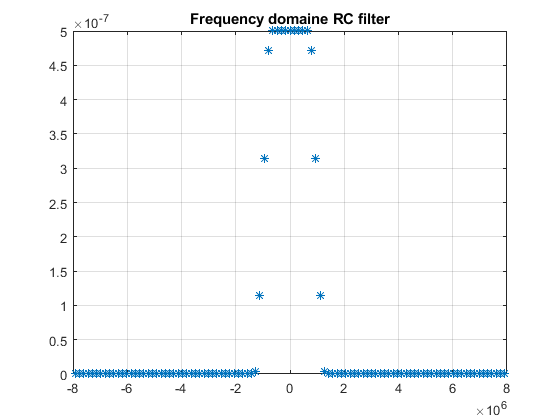


%% Frequency and time space

f_step = fsamp/N;
f_max = f_step*(N-1)/2;
f = linspace(-f_max,f_max,N);

t_step = 1/fsamp;
t = (-(N-1)/2:(N-1)/2)*t_step;

N_point = 11;
zero = zeros(2,N_point);
for n=1:N_point
    zero(1,n) = (-(N_point/2 +0.5)+n)*T_symb;
    if n == (N_point/2 +0.5)
        zero(2,n) = 1;
    end
end

%% filter in the frequency domain

H=zeros(1,N);
%creating the fucntion by the cases given in slide 30 p212
lower_bound = (1-beta)/(2*T);
upper_bound = (1+beta)/(2*T);

for i = 1:N
    fi = abs(f(i));
    if fi < lower_bound
        H(i)=T;
    elseif fi <= upper_bound
        H(i) = T*( 1 + cos( pi*T*(fi - lower_bound)/beta))/2;
    end
end

%% filter in time domain
%Passing from freq to time domain with IFFT

G = sqrt(H); %Root of the filter to implement it at transmiter and receiver

h = ifft(ifftshift(H));
g = ifft(ifftshift(G));
norme = h(1);
h = fftshift(h);
g = fftshift(g);
h_normed = (h/norme);
g_normed = (g/sqrt(norme));

figure(1);plot(f,H,'*'); grid on;title("Frequency domaine RC filter");

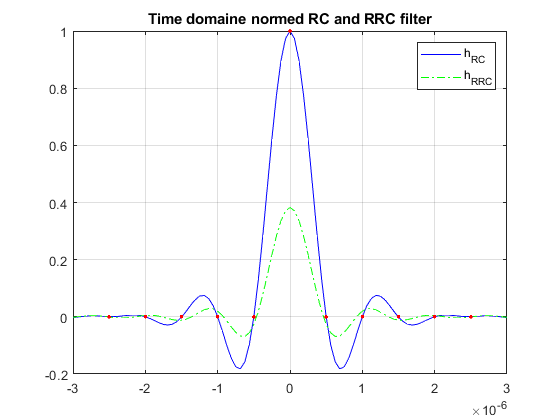

%figure(2);plot(f,G,'*'); grid on;title("Frequency domaine RRC filter");hold on;
%figure(3);plot(t,h); grid on; title("Time domain RC filter");
figure(4);plot(t,h_normed,'b'); grid on; title("Time domaine normed RC and RRC filter");hold on;plot(t,g_normed,'g-.');hold on;
plot(zero(1,:),zero(2,:),'r.');xlim([-0.3 0.3]*1e-5);legend("h_{RC}","h_{RRC}");

## Bit generator, mapping, up-sampling

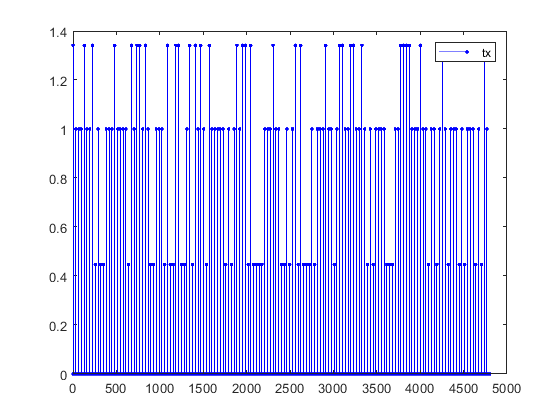

%% Bit Generator

bits = randi(2,1,Nbit)-1;
check_mult = mod(Nbit,Nbps);
if check_mult == 0
    bit_tx = bits;
else
    bit_tx = [bits  zeros(1,Nbps - check_mult)];
end
Nbit_tx = length(bit_tx);


% bit_tx = [0 0 0 1 0 0 0 1];
% Nbit = length(bit_tx);
% Nbit_tx = Nbit;

%% Mapping
%Maps the bits into desired symbols in the complex plane
if (Nbps > 1)
    symb_tx = mapping(bit_tx', Nbps, 'qam')';
else
    symb_tx = mapping(bit_tx', Nbps, 'pam')';
end

%% Upsampling

upsampled_symb_tx = UpSampling(symb_tx,Nbit_tx,Nbps,M);
figure(5);grid on; title("Upsampled Symbols"); stem(abs(upsampled_symb_tx),'b.');legend('tx');

## Filters and Noise

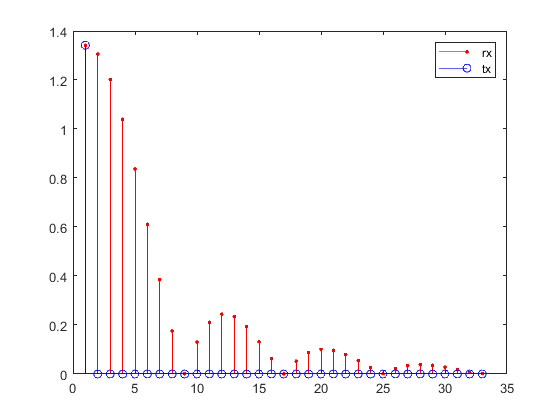

%% Transmitter Filter

signal_tx = conv(upsampled_symb_tx,g_normed);%Convolution of the signal with the filter
signal_tx1 = conv(upsampled_symb_tx(1:M),g_normed);%Convolution of the signal with the filter

signal_tx_simple = upsampled_symb_tx;

%% Transmission Channel

% signal_rx = NoiseAddition(signal_tx,EbNo,fsamp,Nbit);      %With Noise
% signal_rx1 = NoiseAddition(signal_tx1,EbNo,fsamp,Nbps);      %With Noise
% signal_rx_simple = NoiseAddition(signal_tx_simple,EbNo,fsamp,Nbit);      %With Noise

signal_rx = signal_tx;      %With Noise
signal_rx1 = signal_tx1;      %With Noise
signal_rx_simple = signal_tx_simple;      %With Noise


%% Receiver Filter
matched_filter = flip(g_normed); %Get the time reversal of the filter g(-t)
upsampled_symb_rx = conv(signal_rx,matched_filter,'valid'); %Matched filter convolved with the signal; 'valid' to remove padded zeroes added by the convolution
upsampled_symb_rx1 = conv(signal_rx1,matched_filter); %Matched filter convolved with the signal; 'valid' to remove padded zeroes added by the convolution
upsampled_symb_rx1 = upsampled_symb_rx1(N_taps:end-(N_taps-1)+1);

upsampled_symb_rx_simple = signal_rx_simple;

figure(6);grid on;title("Upsampled 1st Symbols without noise");stem(abs(upsampled_symb_rx1),'r.');hold on; stem([abs(upsampled_symb_tx(1:M)) 0],'bo');legend('rx','tx');

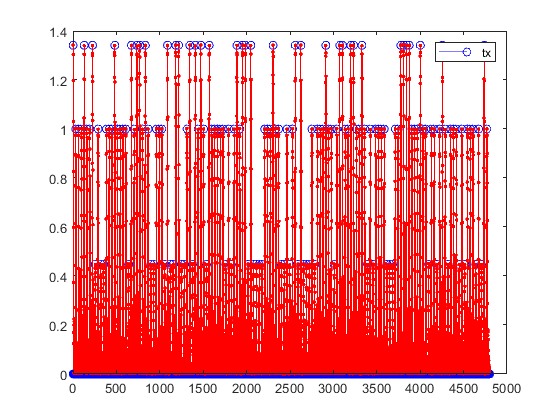

figure(7);grid on; title("Upsampled Symbols"); stem(abs(upsampled_symb_tx),'bo');hold on; stem(abs(upsampled_symb_rx),'r.');legend('tx');

## Down-sampling, demapping and error bit calculator

%% Downsampling

symb_rx = DownSampling(upsampled_symb_rx,Nbit_tx,Nbps,M);
symb_rx_simple = DownSampling(upsampled_symb_rx_simple,Nbit_tx,Nbps,M);

%% Demapping

if (Nbps > 1)
    bit_rx = demapping(symb_rx', Nbps, 'qam')';
else
    bit_rx = demapping(real(symb_rx)', Nbps, 'pam')';
end

bit_down_scaled = bit_rx(1:Nbit);

if (Nbps > 1)
    bit_rx_simple = demapping(symb_rx_simple', Nbps, 'qam')';
else
    bit_rx_simple = demapping(real(symb_rx_simple)', Nbps, 'pam')';
end

bit_down_scaled_simple = bit_rx_simple(1:Nbit);


%% Bits check

ErrorRatio = ErrorCalculator(bit_down_scaled,bits)

ErrorRatio = 0

ErrorRatioSimple = ErrorCalculator(bit_down_scaled_simple,bits)

ErrorRatioSimple = 0

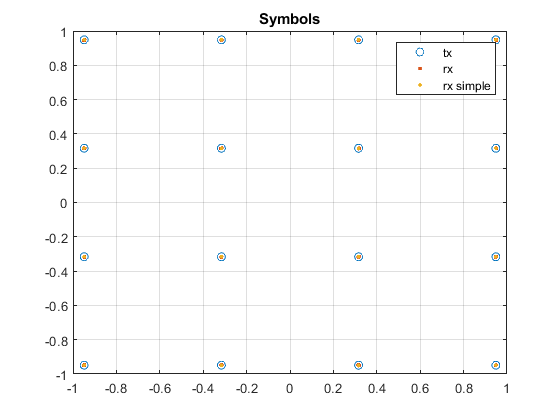

figure(11);plot(symb_tx,'o');grid on; title("Symbols");hold on; plot(symb_rx,'.');plot(symb_rx_simple,'.');hold on;legend('tx','rx','rx simple');